# Projections using Quadrilaterals

## Introduction

In these tutorial files, you will learn how to use the various modules of Swan in order to generate your own FEM and Topology Optimization simulations. In each tutorial, a single building block will be analyzed, with some examples to make it easier. If you have any questions, feel free to create a new issue in the GitHub repository.

In this tutorial, we will learn how to use Projectors with quadrilateral elements in Swan.

## Functions and projectors

A si t has been shown in previous tutorials, functions and and meshes can be represented in Swan. In this case, the mesh created will be constituted by quadrilaterals and the `UnitQuadMesh(n,m)` function can be used, which returns a `Mesh` object of height and width of 1 and divided in `n` elements horizontally and `m` vertically.

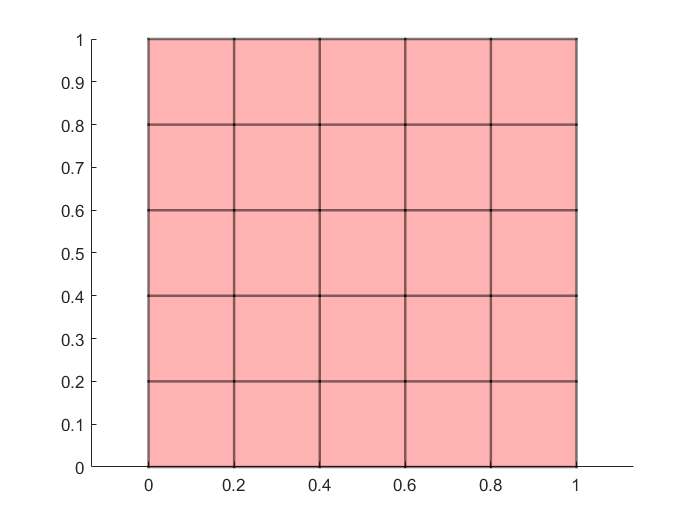

close all;

mesh = UnitQuadMesh(5,5);
figure()
mesh.plot()

Having created a mesh, we can now use the class `AnalyticalFunction`, which uses a function handle to determine the value of the function:

sAF.fHandle = @(x) sin(2*pi*x(1,:,:)); % f(x) = sin(2*pi*x)
sAF.ndimf   = 1; % number of dimensions
sAF.mesh    = mesh;
xFun = AnalyticalFunction(sAF);

We can project this function onto various different spaces, including P0, P1, and P1 Discontinuous:

p0fun = xFun.project('P0');
p1fun = xFun.project('P1');
p2fun = xFun.project('P2');

These functions have additional useful methods:

- *evaluate(xG)*: returns the values of the functions at the given Gauss points

- *plot()*: plot the function in Matlab

- *print(filename, software)*: print the function to visualize it in GiD or Paraview

## Miss anything?

Feel free to create a new Issue in Swan's GitHub repository with any questions or doubts you may have. We will get back to you as soon as possible!